# Digital Signal Processing 

## Special Assignment MATLAB Code

`Ayushi Jain(19BEC015) `

`Himanshu Nakrani(19BEC075)`

`Separation of vocal and musical/instrumental part from an audio file using Fourier Transform`

#### `Code:`

clc;
clear all;
close all;

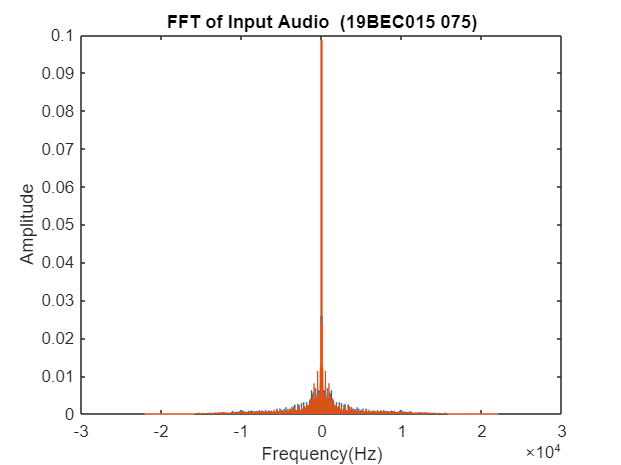

% taking an audio file of .wav format
[audio_in, audio_freq_samp1] = audioread('audio.wav');

% assigning value of length of audio, df is the minimum frequency range
length_audio=length(audio_in);
df = audio_freq_samp1/length_audio;

% frequency values to be assigned on the X-axis of the graph 
frequency_audio = -audio_freq_samp1/2:df:audio_freq_samp1/2-df;

% applying fourier transform on the audio file and ploting FFT of input audio file
FFT_audio_in = fftshift(fft(audio_in)/length(fft(audio_in)));
plot(frequency_audio, abs(FFT_audio_in));
title('FFT of Input Audio  (19BEC015 075)');
xlabel('Frequency(Hz)');
ylabel('Amplitude');



% setting and frequency range   
lower_threshold = 150;
upper_threshold = 2500;

% when values in that array are in that frequency range then we have '1' at
% that index value and '0' for others, i.e. creating boolean (logical) index
% array
val = abs(frequency_audio)<upper_threshold & abs(frequency_audio) > lower_threshold;
FFT_ins = FFT_audio_in(:,1);
FFT_voc = FFT_audio_in(:,1);

% by the logical array, the fourier transform in the frequency range is
% kept in vocals, and rest is kept in instrumental. this is done by setting
% the rest of the values to zero. 
FFT_ins(val) = 0;
FFT_voc(~val) = 0;

% now we perform the inverse fourier transform to get back the signal 
FFT_a = ifftshift(FFT_audio_in);
FFT_a11 = ifftshift(FFT_ins);
FFT_a31 = ifftshift(FFT_voc);

% creating the time domain signal 
s1 = ifft(FFT_a11*length(fft(audio_in)));
s3 = ifft(FFT_a31*length(fft(audio_in)));

% writing into the file
audiowrite('audio_instrumentals.wav', s1, audio_freq_samp1);
audiowrite('audio_vocals.wav', s3, audio_freq_samp1);

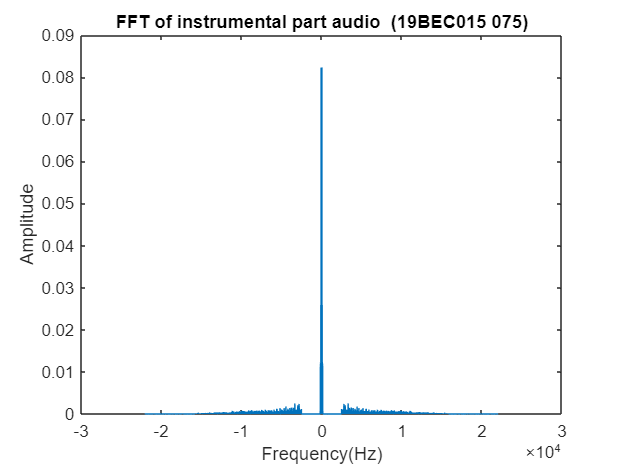

% ploting FFT of output signal which contains instrumental part
[audio_in_1, audio_freq_samp1_1] = audioread('audio_instrumentals.wav');
length_audio_1=length(audio_in_1);
df_1 = audio_freq_samp1_1/length_audio_1;
frequency_audio_1 = -audio_freq_samp1_1/2:df_1:audio_freq_samp1_1/2-df_1;
FFT_audio_in_1 = fftshift(fft(audio_in_1)/length(fft(audio_in_1)));
plot(frequency_audio_1, abs(FFT_audio_in_1));
title('FFT of instrumental part audio  (19BEC015 075)');
xlabel('Frequency(Hz)');
ylabel('Amplitude');

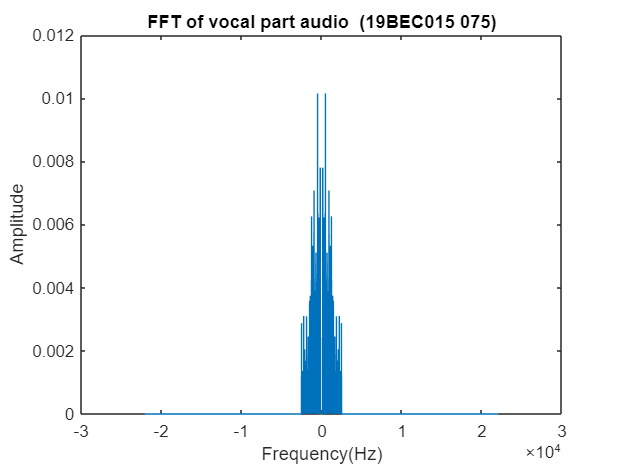

% ploting FFT of output signal which contains vocal part
[audio_in_2, audio_freq_samp1_2] = audioread('audio_vocals.wav');
length_audio_2=length(audio_in_2);
df_2 = audio_freq_samp1_2/length_audio_2;
frequency_audio_2 = -audio_freq_samp1_2/2:df_2:audio_freq_samp1_2/2-df_2;
FFT_audio_in_2 = fftshift(fft(audio_in_2)/length(fft(audio_in_2)));
plot(frequency_audio_2, abs(FFT_audio_in_2));
title('FFT of vocal part audio  (19BEC015 075)');
xlabel('Frequency(Hz)');
ylabel('Amplitude');

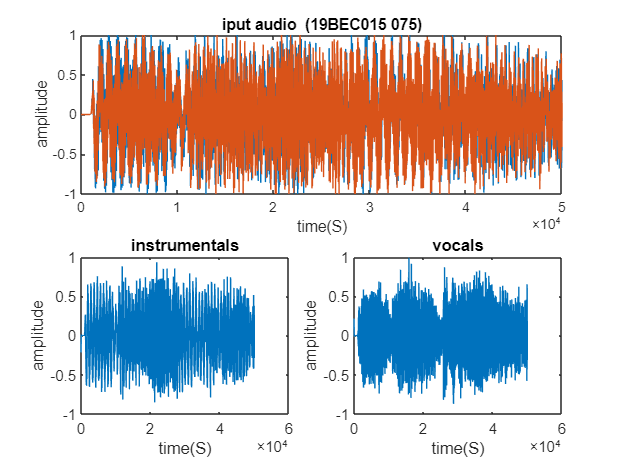

% ploting input audio signal
[a, fs] = audioread('audio.wav');
b=a([1:50000],:);
subplot(2,2,[1,2]);

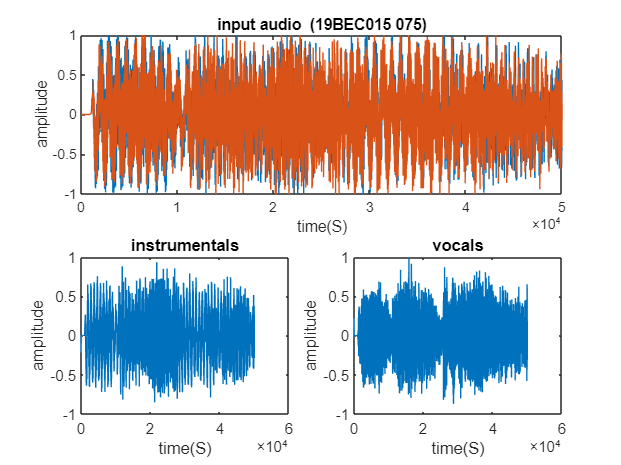

plot(b)
title('input audio  (19BEC015 075)');
xlabel('time(S)');
ylabel('amplitude');

% ploting output audio with instrumental part
[a1, fs1] = audioread(['audio_instrumentals.wav']);
b1=a1([1:50000],:);
subplot(2,2,3);
plot(b1)
title('instrumentals');
xlabel('time(S)');
ylabel('amplitude');

% ploting output audio with vocal part
[a2, fs2] = audioread('audio_vocals.wav');
b2=a2([1:50000],:);
subplot(2,2,4);
plot(b2)
title('vocals');
xlabel('time(S)');
ylabel('amplitude');

% audio file information
info = audioinfo('audio.wav')

info = struct with fields:
             Filename: 'H:\MATLAB\files\DSP\ASSIGNMENT\audio.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 2
           SampleRate: 44100
         TotalSamples: 882000
             Duration: 20
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16
